# Short Project

## Detector d'ulls

Miquel Gotanegra

                                                                                                                                                                                                                                                                                                               Josep Navarro


% Primerament procedirem a carregar les imatges de les cares i no cares de la base
% de dades que hem obtingut mitjançant el codi en Python que tenim adjuntat
% al document explicatiu del ShortProject.

%Fem un clear per esborrar tot el que tinguem al workspace
clear

%Llegim les imatges de les cares i procedim a fer un redimensionament a més
%de convertir la imatge a 256 nivells de gris
list = dir('Cares\*.jpg');
FilesUlls = length(list);
%Creem un conjunt de les imatges de la carpeta
Ulls = cell(1,length(list));

%%seleccionem nomes els ulls, ja que si no fariem un detector de cares, en
%%relacio 4:3
mida = 50;
dimx = mida*4;
dimy= mida*3;
eyeCenter = [381 476];
for i=1:FilesUlls
    image_file=imread(list(i).name);
    I = rgb2gray(image_file);
    I = I(eyeCenter(2)-dimy/2:eyeCenter(2)+dimy/2,eyeCenter(1)-dimy/2:eyeCenter(1)+dimx/2);
    Ulls{i}=I;
end
list = dir('No_ulls\*.jpg');
FilesNoUlls = length(list);
No_ulls = cell(1,length(list));
%%guardem un fragment aleatori de la mateixa mida que el ull
for j=1:FilesNoUlls
    image_file=imread(list(j).name);
    I = rgb2gray(image_file);
    win = randomWindow2d(size(I),[dimy,dimx]);
    I = imcrop(I,win);
    No_ulls{j}=I;
end




%%Podem dividir la imatge en blocs seguint la idea del LBP i agafem les característiques de cada secció
%% la imatge esta en 3:2, per tant probarem amb 3,6 i 12 blocs

%% per al myDescriptorFull, sense dividir la imatge

DescriptorTypes = {'Mitjana','Variança','Desviacio','GradientMag','Deteccio'};

%% per al myDescriptor3
DescriptorType3 = {'Mitjana 1','Variança 1','Desviacio 1','GradientMag 1',...
                    'Mitjana 2','Variança 2','Desviacio 2','GradientMag 2',...
                    'Mitjana 3','Variança 3','Desviacio 3','GradientMag 3',...
                    'Deteccio'};

%% per al myDescriptor6
DescriptorType6 = cat(2,DescriptorType3(1:end-1),{
                    'Mitjana 4','Variança 4','Desviacio 4','GradientMag 4',...
                    'Mitjana 5','Variança 5','Desviacio 5','GradientMag 5',...
                    'Mitjana 6','Variança 6','Desviacio 6','GradientMag 6',...
                    'Deteccio'});

DescriptorType12 = cat(2,DescriptorType6(1:end-1),{
                    'Mitjana 7','Variança 7','Desviacio 7','GradientMag 7',...
                    'Mitjana 8','Variança 8','Desviacio 8','GradientMag 8',...
                    'Mitjana 9','Variança 9','Desviacio 9','GradientMag 9',...
                    'Mitjana 10','Variança 10','Desviacio 10','GradientMag 10',...
                    'Mitjana 11','Variança 11','Desviacio 11','GradientMag 11',...
                    'Mitjana 12','Variança 12','Desviacio 12','GradientMag 12',...
                    'Deteccio'});


%%S'ha de fer fora del bucle perque si inicialitzem una taula buida tots
%%els elements estan com a doubles
DescriptorFull = array2table(myDescriptorFull(Ulls{1}));
%posem categorical per a que nomes hi hagi dues opcions a l'hora de fer la predicció,
%ulls o no-ulls; si posesim un string normal n'hi hauria infinites
DescriptorFull.Deteccio = categorical({'Ulls'});
DescriptorFull.Properties.VariableNames = DescriptorTypes;

for i=2:FilesUlls
    fila = array2table(myDescriptorFull(Ulls{i}));
    fila.Deteccio = categorical({'Ulls'});
    fila.Properties.VariableNames = DescriptorTypes;
    DescriptorFull = [DescriptorFull;fila];
    
end
for i = 1:FilesNoUlls
    fila = array2table(myDescriptorFull(No_ulls{i}));
    fila.Deteccio = categorical({'No-Ulls'});
    fila.Properties.VariableNames = DescriptorTypes;
    DescriptorFull = [DescriptorFull;fila];
end
DescriptorFull;
writetable(DescriptorFull,'DescriptorFull.csv','Delimiter',',','QuoteStrings',true)
[trainedClassifierFull, validationAccuracyFull] = trainClassifierFull(DescriptorFull); 
validationAccuracyFull

validationAccuracyFull = 0.7414

MeritFull = sqrt( (1-size(DescriptorFull,2)/(48*32))^2  + validationAccuracyFull^2)

MeritFull = 1.2423

Descriptor3 = array2table(myDescriptor3(Ulls{1}));
Descriptor3.Deteccio = categorical({'Ulls'});
Descriptor3.Properties.VariableNames = DescriptorType3;

for i=2:FilesUlls
    fila = array2table(myDescriptor3(Ulls{i}));
    fila.Deteccio = categorical({'Ulls'});
    fila.Properties.VariableNames = DescriptorType3;
    Descriptor3 = [Descriptor3;fila];
    
end
for i = 1:FilesNoUlls
    fila = array2table(myDescriptor3(No_ulls{i}));
    fila.Deteccio = categorical({'No-Ulls'});
    fila.Properties.VariableNames = DescriptorType3;
    Descriptor3 = [Descriptor3;fila];
end
Descriptor3;
writetable(Descriptor3,'Descriptor3.csv','Delimiter',',','QuoteStrings',true)
[trainedClassifier3, validationAccuracy3] = trainClassifier3(Descriptor3); 
validationAccuracy3

validationAccuracy3 = 0.9486

Merit3 = sqrt( (1-size(Descriptor3,2)/(48*32))^2  + validationAccuracy3^2)

Merit3 = 1.3722

Descriptor6 = array2table(myDescriptor6(Ulls{1}));
Descriptor6.Deteccio = categorical({'Ulls'});
Descriptor6.Properties.VariableNames = DescriptorType6;

for i=2:FilesUlls
    fila = array2table(myDescriptor6(Ulls{i}));
    fila.Deteccio = categorical({'Ulls'});
    fila.Properties.VariableNames = DescriptorType6;
    Descriptor6 = [Descriptor6;fila];
    
end
for i = 1:FilesNoUlls
    fila = array2table(myDescriptor6(No_ulls{i}));
    fila.Deteccio = categorical({'No-Ulls'});
    fila.Properties.VariableNames = DescriptorType6;
    Descriptor6 = [Descriptor6;fila];
end
Descriptor6;
writetable(Descriptor6,'Descriptor6.csv','Delimiter',',','QuoteStrings',true)
[trainedClassifier6, validationAccuracy6] = trainClassifier6(Descriptor6); 
validationAccuracy6

validationAccuracy6 = 0.9700

Merit6 = sqrt( (1-size(Descriptor6,2)/(48*32))^2  + validationAccuracy6^2)

Merit6 = 1.3815

Descriptor12 = array2table(myDescriptor12(Ulls{1}));
Descriptor12.Deteccio = categorical({'Ulls'});
Descriptor12.Properties.VariableNames = DescriptorType12;

for i=2:FilesUlls
    fila = array2table(myDescriptor12(Ulls{i}));
    fila.Deteccio = categorical({'Ulls'});
    fila.Properties.VariableNames = DescriptorType12;
    Descriptor12 = [Descriptor12;fila];
    
end
for i = 1:FilesNoUlls
    fila = array2table(myDescriptor12(No_ulls{i}));
    fila.Deteccio = categorical({'No-Ulls'});
    fila.Properties.VariableNames = DescriptorType12;
    Descriptor12 = [Descriptor12;fila];
end
Descriptor12;
writetable(Descriptor12,'Descriptor12.csv','Delimiter',',','QuoteStrings',true)
%%ens quedem amb 12 blocs i tots els descriptors, que es com ens dona millors resultats
[trainedClassifier12, validationAccuracy12] = trainClassifier12(Descriptor12); 
validationAccuracy12

validationAccuracy12 = 0.9629

Merit12 = sqrt( (1-size(Descriptor12,2)/(48*32))^2  + validationAccuracy12^2)

Merit12 = 1.3654

C =imread('mj.png');
I = rgb2gray(C);
[x y] = size(I)

x = 362

y = 364

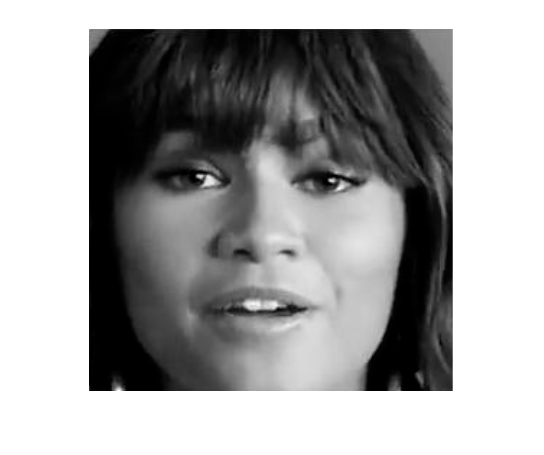

%% fem les proves amb un frame concret del video per calcular mes o menys la posicio dels ulls
imshow(I);

stepy = round(y/6)

stepy = 61

stepx = round(x/8)

stepx = 45

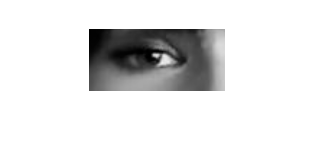


UllDret = I(2*stepy:stepy*3,stepx:stepx*4);
UllEsquerre = I(2*stepy:stepy*3,stepx*4:stepx*7);
imshow(UllDret)

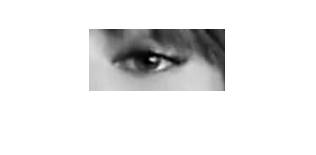

imshow(UllEsquerre)

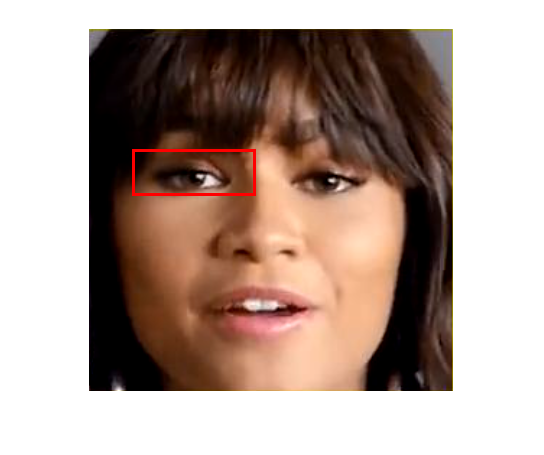



fila = array2table(myDescriptor12(UllDret));
fila.Properties.VariableNames = DescriptorType12(1:end-1);
if trainedClassifier12.predictFcn(fila) == categorical({'Ulls'})
    K = insertShape(C,'Rectangle',[stepx,2*stepy,stepy*2,stepx],'Color','red','LineWidth',3);
end
imshow(K)

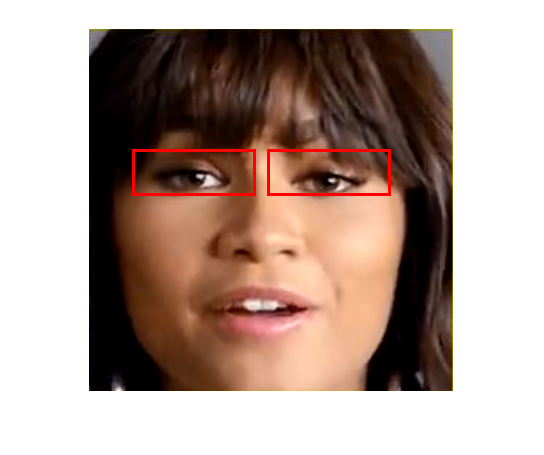

fila = array2table(myDescriptor12(UllEsquerre));
fila.Properties.VariableNames = DescriptorType12(1:end-1);
if trainedClassifier12.predictFcn(fila) == categorical({'Ulls'})
    K = insertShape(K,'Rectangle',[4*stepx,2*stepy,stepy*2,stepx],'Color','red','LineWidth',3);
end
imshow(K)

% Create a cascade detector object. 

Detector = vision.CascadeObjectDetector('FrontalFaceLBP'); 
delete 'edit.avi'
edit  = VideoWriter('edit.avi');
open(edit)
% Read a video frame and run the face detector. 

videoReader = VideoReader('Zendaya.mp4'); 

  

while hasFrame(videoReader) 

    % get the next frame 

    videoFrame = readFrame(videoReader); 

    bbox = step(Detector, videoFrame); 
    % Draw the returned bounding box around the detected face. 
    videoFrame = insertShape(videoFrame, 'Rectangle', bbox); 
   
    for i = 1:size(bbox,1)
        caja = bbox(i,:);
        y = caja(1);
        x = caja(2);
        stepy = caja(3);
        stepx = caja(4);
        C = videoFrame(x:x+stepx,y:y+stepy,:);
        I = rgb2gray(C);

        [f c] = size(I);
        stepy = round(c/6);
        stepx = round(f/8);
    
        %%pel cas concret de la Zendaya, les deteccions son a k=2, pero
        %%pensem que buscant els ulls en un espai vertical mes ampli ens
        %%ajuda a abarcar mes tipus de cares diferents (mirem a la part superior de la imatge nomes<)
        for k=1:3
            UllDret = I(k*stepy:stepy*(k+1),stepx:stepx*4);
            UllEsquerre = I(k*stepy:stepy*(k+1),stepx*4:stepx*7);
            fila = array2table(myDescriptor12(UllDret));
            fila.Properties.VariableNames = DescriptorType12(1:end-1);
            if trainedClassifier12.predictFcn(fila) == categorical({'Ulls'})
                videoFrame = insertShape(videoFrame,'Rectangle',[caja(1) + stepx, caja(2) + 2*stepy,stepy*2,stepx],'Color','red','LineWidth',3);
            end
            
            fila = array2table(myDescriptor12(UllEsquerre));
            fila.Properties.VariableNames = DescriptorType12(1:end-1);
            if trainedClassifier12.predictFcn(fila) == categorical({'Ulls'})
                videoFrame = insertShape(videoFrame,'Rectangle',[caja(1) + 4*stepx,caja(2)+2*stepy,stepy*2,stepx],'Color','red','LineWidth',3);
            end
        end

    end
        writeVideo(edit,videoFrame)
end 
close(edit)